# Jacobian

clc
clear
close all

Until now, we have practiced with the kinematics related to positions thanks to the FK and the IK. But we can also think in terms of joint velocities that the joints generate when they try to reach a joint position, so there is also a part of kinematics related to the velocities. 

*The Jacobian matrix maps those velocities: The velocity of the joints and the spatial velocity of the end-effectori. *In particular:

$v = J(q)\dot{q}$ where $J(q)$ is the Jacobian matrix,$\dot{q} = (\dot{q_1}...\dot{q_n})$ is the vector of joint velocities and $v = (v_x, v_y, v_z, \omega_x, \omega_y, \omega_z)$

If $J(q)$ is invertible (square matrix, det($J(q)$≠ 0), then we can say: $\dot{q} = J(q)^{-1}v$

We can compute $\frac{𝜕𝑝}{ 𝜕𝑞} = 𝐽(𝑞)$ with the partial derivatives of the end effector position $p$ with respect to each component of $q$

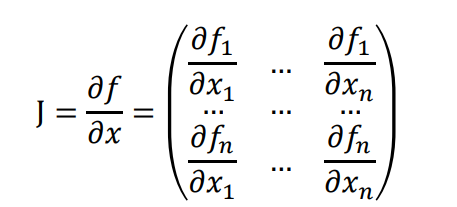

#### Example 1 (Jacobian symbolic model ETS2):

syms a1 a2 real
e2link = ETS2.Rz("q1")*ETS2.Tx(a1)*ETS2.Rz("q2")*ETS2.Tx(a2);

We compute the FK for generic $q_1$ and $q_2$, so we can extract the end effector position, and compute the Jacobian

syms q1 q2 real
TE=e2link.fkine([q1 q2]);
p=TE(1:2,3);
J=jacobian(p,[q1 q2])

$$J = \left(\begin{array}{cc} -a_{2}\,\sin\left(q_{1}+q_{2}\right)-a_{1}\,\sin\left(q_{1}\right) & -a_{2}\,\sin\left(q_{1}+q_{2}\right)\\ a_{2}\,\cos\left(q_{1}+q_{2}\right)+a_{1}\,\cos\left(q_{1}\right) & a_{2}\,\cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

#### Example 2 (Jacobian rbt structure):

For any robot object in MATLAB (built using rigidBodyTree structure), one can use the geometricJacobian function

[puma,conf]=loadrvcrobot("puma");
J=puma.geometricJacobian(conf.qn,"link6")

J =    -0.0000    0.0000    0.0000    0.7071    0.0000    1.0000
   -0.0000   -1.0000   -1.0000   -0.0000   -1.0000   -0.0000
    1.0000    0.0000    0.0000   -0.7071    0.0000   -0.0000
    0.1501    0.0144    0.3197    0.0000         0         0
    0.5963    0.0000    0.0000   -0.0000         0         0
         0    0.5963    0.2910    0.0000         0         0


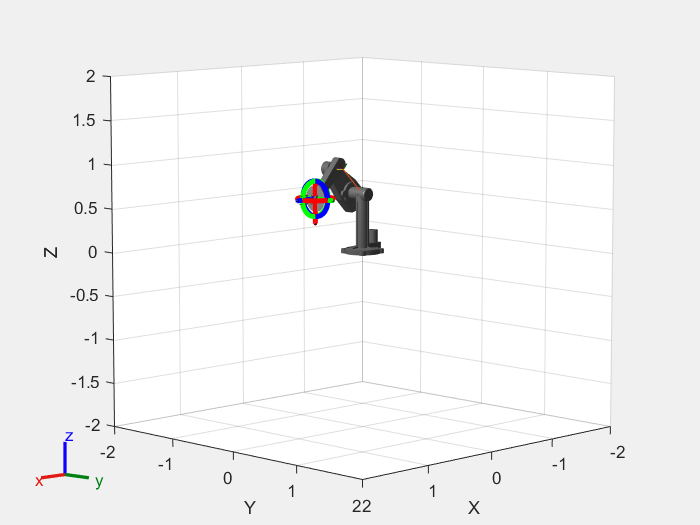

irbt =   interactiveRigidBodyTree with properties:

           RigidBodyTree: [1×1 rigidBodyTree]
                IKSolver: [1×1 generalizedInverseKinematics]
       SolverPoseWeights: [1 1]
             Constraints: {}
          MarkerBodyName: 'link6'
     MarkerControlMethod: 'InverseKinematics'
       MarkerScaleFactor: 1
              ShowMarker: 1
           Configuration: [6×1 double]
    StoredConfigurations: []
              MarkerPose: [4×4 double]
          MarkerBodyPose: [4×4 double]


irbt = interactiveRigidBodyTree(puma, Configuration=conf.qn)

NOTE! The results of the Jacobian matrix returned by *geometricJacobian* are read in a different order. The rows correspond to the task space degree of freedom in this order: 


$$v = (\omega_x, \omega_y, \omega_z, v_x, v_y, v_z)$$


#### Example 3: Singularities

Jacobian matrices are also used to check the singularity condition of a manipulator: it occurs when at a certain configuration, the robot losses a degree of freedom (**joint alignment or joint at maximum reach**). 

J_sing = puma.geometricJacobian(conf.qr,"link6")

J_sing =          0         0         0         0         0         0
         0   -1.0000   -1.0000         0   -1.0000         0
    1.0000    0.0000    0.0000    1.0000    0.0000    1.0000
    0.1500   -0.8636   -0.4318         0         0         0
    0.0203    0.0000    0.0000         0         0         0
         0    0.0203    0.0203         0         0         0


In fact, we can look at the determinant of the Jacobian matrix

det(J_sing)

ans = 0

rank(J_sing)

ans = 5

The singularity is due to the fact that $q_5 = 0$ then $q_4$ and $q_6$ are aligned.

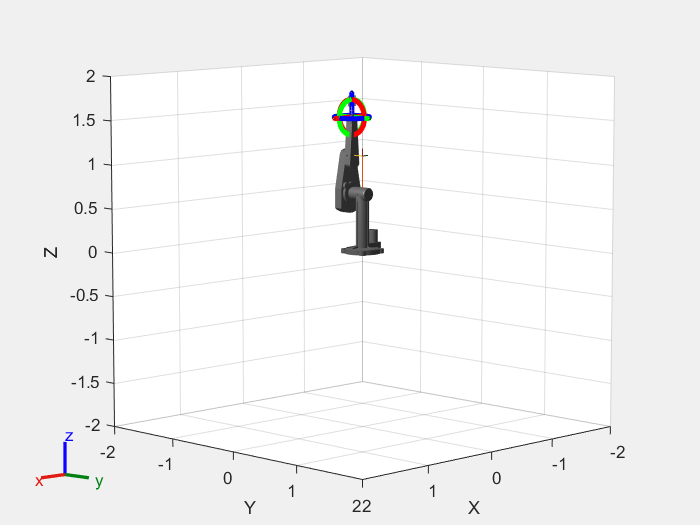

irbt_sing =   interactiveRigidBodyTree with properties:

           RigidBodyTree: [1×1 rigidBodyTree]
                IKSolver: [1×1 generalizedInverseKinematics]
       SolverPoseWeights: [1 1]
             Constraints: {}
          MarkerBodyName: 'link6'
     MarkerControlMethod: 'InverseKinematics'
       MarkerScaleFactor: 1
              ShowMarker: 1
           Configuration: [6×1 double]
    StoredConfigurations: []
              MarkerPose: [4×4 double]
          MarkerBodyPose: [4×4 double]


irbt_sing = interactiveRigidBodyTree(puma, Configuration=conf.qr)

The fact that the robot is near a singularity position, means that it will need a lot of effort (other joint velocities) to pull out the robot of that configuration and resume movements. So even if $q_5$ is small, but near to zero, like $q_5=5\degree 
$ :

qns = conf.qr;
qns(5)=deg2rad(5);
J=puma.geometricJacobian(qns,"link6");
qd=inv(J)*[0 0 0 0 0 0.1]';
qd' %just observe the result in a row

ans =    -0.0000   -4.9261    9.8522    0.0000   -4.9261   -0.0000


det(J) %near 0

ans = 1.5509e-05

### Velocity Ellipsoid

In a graphical way, we can "see" the singularity effect by computing an ellipse which is proportional to the veolcities, and it is described by: 

#### Example: (Ellipse 2D)

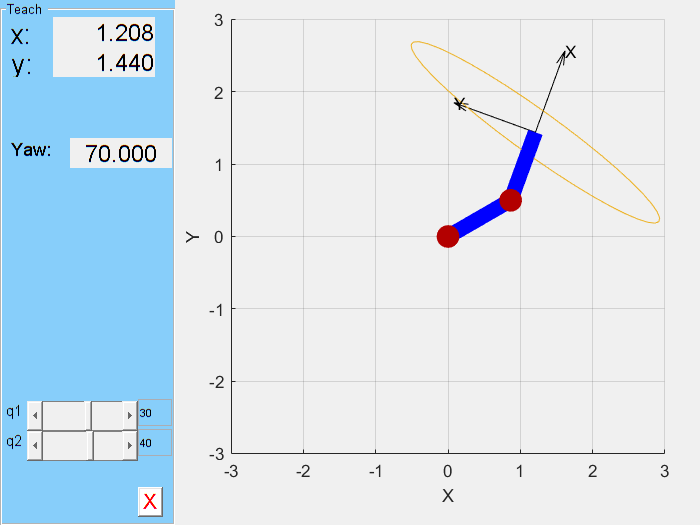

planar2=ETS2.Rz("q1")*ETS2.Tx(1)*ETS2.Rz("q2")*ETS2.Tx(1);
planar2.teach(deg2rad([30 40]),"vellipse")

#### Example: (Ellipse 3D)

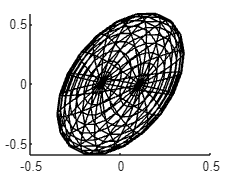

J=puma.geometricJacobian(conf.qn,"link6");
Jt=J(4:6,:); %for translational velocity ellipsoid
Et=inv(Jt*Jt'); 
figure
plotellipsoid(Et) 

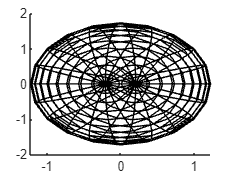

Jr=J(1:3,:); %for rotational velocity ellipsoid
Er=inv(Jr*Jr');
figure
plotellipsoid(Er)

### Non-square Jacobian

When N ≠ 6, we have a non-square Jacobian, and it would be troublesome to do the computations

- If N < 6, we have an underactuated robot (less joints than degrees of freedom)

- If N > 6, we have an over-actuated robot (also known as redundant robot)

Fortunately, if the Jacobian $J(q)$ for N < 6 has full column rank (all the columns are linearly independent, not in a singularity configuration), it is possible to apply compute the pseudoinverse of $J(q)$ 


$$\dot{q} = J(q)^+v$$
  

where $J(q)^+ = [J(q)^TJ(q)]^{-1}J(q)^T$ is the pseudoinverse of  $J(q)$

In MATLAB is computed using the command *pinv*